# Online analysis (single patient)

Analyze data about one patient:

- Extract EEG data

- Apply Laplacian filter and compute PSD

- Evaluate single sample accuracy

- Evaluate accuracy using evidence accumulation

- Further evaluate after tuning the parameters on the first online run

clearvars; clc;
patients = find_patients('data');
patient = patients{1};
classifiers_fold_root = '../classifiers/';
results_fold_root = '../online-results/';

disp(strcat('Beginning data Analysis for patient: ', patient.name));

Beginning data Analysis for patient:ai6


info.fixation_code = 786;
info.cue_BH = 773;
info.cue_BF = 771;
info.cue_rest = 783;
info.feedback_code = 781;

info.selected_frequencies = (4:2:48)';
info.channel_labels  = {'Fz', 'FC3', 'FC1', 'FCz', 'FC2', 'FC4', 'C3', 'C1', 'Cz', 'C2', 'C4', 'CP3', 'CP1', 'CPz', 'CP2', 'CP4'};

## Process online data - apply Laplacian filter and compute PSD

PSD_data = cell(size(patient.online_files));
for f = 1:length(patient.online_files)
    % Raw EEG
    [s, h] = sload(patient.online_files{f});
    
    % Apply Lap and compute PSD
    PSD_data{f} = psd_extraction(s, h);
end

[proc] |- Applying Laplacian
[proc] |- Computing spectrogram
[proc] |- Extracting and converting the events
[proc] |- Applying Laplacian
[proc] |- Computing spectrogram
[proc] |- Extracting and converting the events
[proc] |- Applying Laplacian
[proc] |- Computing spectrogram
[proc] |- Extracting and converting the events
[proc] |- Applying Laplacian
[proc] |- Computing spectrogram
[proc] |- Extracting and converting the events
[proc] |- Applying Laplacian
[proc] |- Computing spectrogram
[proc] |- Extracting and converting the events
[proc] |- Applying Laplacian
[proc] |- Computing spectrogram
[proc] |- Extracting and converting the events


Here we suppose the frequecies of the PSD don't change between the files

info.frequencies = PSD_data{1}.frequencies;
[PSD, EVENT, run_k] = concatenatePSD(PSD_data);

## Create Cue and Trial vectors

[cue_k, trial_k] = label_data(EVENT, length(PSD));

## Apply log and select a grid of frequencies

[PSD, info.frequencies] = extract_frequencies(PSD, info.frequencies, info.selected_frequencies);
PSD = log(PSD); 

## Load classifier and Evidence Accumulation parameters

load(strcat(classifiers_fold_root, patient.name, '_classifier'));
if(isvarname('exp_param') && isvarname('dyn_param') && isvarname('mov_param'))
    %Save the parameters coming from offline data in different names
    off_exp_param = exp_param;
    off_dyn_param = dyn_param;
    off_mov_param = mov_param;
end


## Extract features from PSD based on offline Fisher score

dataset = extract_features(PSD, selected_features); 
% features were selected in the script for training on offline data

# Single sample performance on online data

## Extract test set

classes = [info.cue_BF, info.cue_BH];
bh_index = (cue_k== info.cue_BH);
bf_index = (cue_k== info.cue_BF);

test_set = dataset(bh_index | bf_index, :);
true_labels = cue_k(bh_index | bf_index);

## Test the model on online data

predicted_labels = predict(model, test_set);
[accuracy, accuracy_per_class] = evaluate_classifier(true_labels, predicted_labels, classes)

accuracy = 70.8340

accuracy_per_class =    66.6448   74.3653


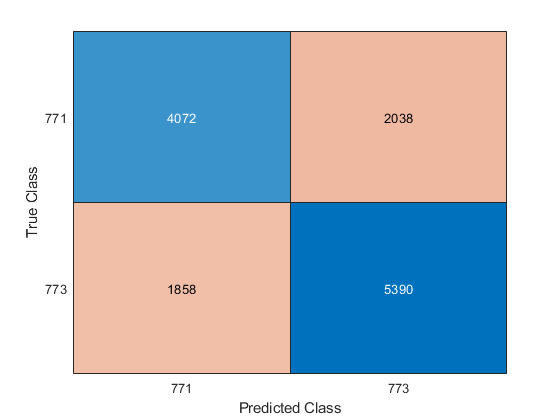

cm = confusionchart(true_labels, predicted_labels);

confusion_matrix = cm.NormalizedValues;
confusion_matrix_labels = cm.ClassLabels;

save(strcat(results_fold_root, patient.name, '_single_sample'),'accuracy', 'accuracy_per_class', 'confusion_matrix', 'confusion_matrix_labels');

## Separate into tuning data (first online run) and test data (rest of online data)

% online data of the first day
tuning_index = (run_k==1);

data_tuning = dataset(tuning_index, :);
data_test = dataset(~tuning_index, :);

trial_k_tuning = trial_k(tuning_index);
trial_k_test = trial_k(~tuning_index);

true_class = EVENT.TYP(EVENT.TYP==info.cue_BF | EVENT.TYP==info.cue_BH | EVENT.TYP==info.cue_rest);
num_trials_tuning = length(nonzeros(unique(trial_k_tuning)));
true_class_tuning = true_class(1:num_trials_tuning);
true_class_test = true_class(num_trials_tuning + 1:end);

feedbk_ind = labels_for_event(EVENT, info.feedback_code, length(PSD));
feedbk_ind_tuning = feedbk_ind(tuning_index);
feedbk_ind_test = feedbk_ind(~tuning_index);


%predict on data
[~,post_prob_whole] = predict(model, dataset);
[~,post_prob_tuning] = predict(model, data_tuning);
[~,post_prob_test] = predict(model, data_test);

% vector of start of feedback for each trial
feedbk_starts = EVENT.POS(EVENT.TYP==info.feedback_code);
feedbk_starts_tuning = feedbk_starts(1 : num_trials_tuning);
feedbk_starts_test = feedbk_starts(num_trials_tuning+1 : end);
% map the feedback starts for test to start from the first data after tuning
feedbk_starts_test = feedbk_starts_test - size(data_tuning, 1);

# Evidence accumulation with parameters from offline tuning

## Classify data

free_force = @(ampl,w) (@(x) f_free(x, ampl, w));
bmi_force = @(x) f_bmi(x);

off_tun_accumulator_ex = exponential_smoothing(post_prob_whole, feedbk_starts, off_exp_param.alpha);
off_tun_accumulator_dyn = dynamic_smoothing(post_prob_whole, feedbk_starts, off_dyn_param.alpha, ...
    off_dyn_param.beta, free_force(off_dyn_param.amp, off_dyn_param.w), bmi_force);
off_tun_accumulator_mov = mov_avg_smoothing(post_prob_whole, feedbk_starts, off_mov_param.alpha);

## Accuracy

[off_tun_perf_active_ex, off_tun_perf_resting_ex, off_tun_perf_active_rej_ex] = evaluate_accumulation(off_exp_param.up_threshold, off_exp_param.down_threshold, ...
    true_class, off_tun_accumulator_ex, feedbk_ind, trial_k)

off_tun_perf_active_ex = 82.5000

off_tun_perf_resting_ex = NaN

off_tun_perf_active_rej_ex = 83.8983

[off_tun_perf_active_dyn, off_tun_perf_resting_dyn, off_tun_perf_active_rej_dyn] = evaluate_accumulation(off_dyn_param.up_threshold, off_dyn_param.down_threshold, ...
    true_class, off_tun_accumulator_dyn, feedbk_ind, trial_k)

off_tun_perf_active_dyn = 81.6667

off_tun_perf_resting_dyn = NaN

off_tun_perf_active_rej_dyn = 83.7607

[off_tun_perf_active_mov, off_tun_perf_resting_mov, off_tun_perf_active_rej_mov] = evaluate_accumulation(off_mov_param.up_threshold, off_mov_param.down_threshold, ...
    true_class, off_tun_accumulator_mov, feedbk_ind, trial_k)

off_tun_perf_active_mov = 55.8333

off_tun_perf_resting_mov = NaN

off_tun_perf_active_rej_mov = 62.6168


save(strcat(results_fold_root, patient.name, '_off_tuning_test_ev_acc'), 'off_tun_perf_active_ex', 'off_tun_perf_resting_ex', 'off_tun_perf_active_rej_ex', ...
    'off_tun_perf_active_dyn', 'off_tun_perf_resting_dyn', 'off_tun_perf_active_rej_dyn', 'off_tun_perf_active_mov', 'off_tun_perf_resting_mov', 'off_tun_perf_active_rej_mov');

# Evidence Accumulation tuning

We now use the online data from the first online run to tune new parameters for evidence accumulation.

The performance of the new parameters is then evaluated on the other online runs.

## Exponential smoothing

framework = @(alpha) exponential_smoothing(post_prob_tuning, feedbk_starts_tuning, alpha);
evaluation = @(x) fitness(x(2), x(3), true_class_tuning, framework(x(1)), feedbk_ind_tuning, trial_k_tuning);
params = ga(evaluation, 3, [], [], [], [], [0 0.5 0], [1 1 0.5]); 

Optimization terminated: average change in the fitness value less than options.FunctionTolerance.



exp_param.alpha = params(1);
exp_param.up_threshold = params(2);
exp_param.down_threshold = params(3);

## Dynamic smoothing

free_force = @(ampl,w) (@(x) f_free(x, ampl, w));
bmi_force = @(x) f_bmi(x);

framework = @(alpha, beta, ampl, w) dynamic_smoothing(post_prob_tuning, feedbk_starts_tuning, alpha, beta, free_force(ampl, w), bmi_force);
evaluation = @(x) fitness(x(5), x(6), true_class_tuning, framework(x(1),x(2),x(3),x(4)), feedbk_ind_tuning, trial_k_tuning);
params = ga(evaluation, 6, [], [], [], [], [0 0 0 0 0.5 0], [1 1 1 0.5 1 0.5]); 

Optimization terminated: average change in the fitness value less than options.FunctionTolerance.



dyn_param.alpha = params(1);
dyn_param.beta = params(2);
dyn_param.amp = params(3);
dyn_param.w = params(4);
dyn_param.up_threshold = params(5);
dyn_param.down_threshold = params(6);

## Moving average

framework = @(alpha) mov_avg_smoothing(post_prob_tuning, feedbk_starts_tuning, alpha);
evaluation = @(x) fitness(x(2), x(3), true_class_tuning, framework(x(1)), feedbk_ind_tuning, trial_k_tuning);
params = ga(evaluation, 3, [], [], [], [], [0 0.5 0], [1 1 0.5]); 

Optimization terminated: average change in the fitness value less than options.FunctionTolerance.



mov_param.alpha = params(1);
mov_param.up_threshold = params(2);
mov_param.down_threshold = params(3);

## Save new fine-tuned parameters

save(strcat(results_fold_root, patient.name, '_online_tuning_params'), 'exp_param', 'dyn_param', 'mov_param');

# Evidence accumulation performance on the tuning data

## Classify data

accumulator_ex = exponential_smoothing(post_prob_tuning, feedbk_starts_tuning, exp_param.alpha);
accumulator_dyn = dynamic_smoothing(post_prob_tuning, feedbk_starts_tuning, dyn_param.alpha, ...
    dyn_param.beta, free_force(dyn_param.amp, dyn_param.w), bmi_force);
accumulator_mov = mov_avg_smoothing(post_prob_tuning, feedbk_starts_tuning, mov_param.alpha);

## Accuracy

[perf_active_ex, perf_resting_ex, perf_active_rej_ex] = evaluate_accumulation(exp_param.up_threshold, exp_param.down_threshold, true_class_tuning, accumulator_ex, feedbk_ind_tuning, trial_k_tuning)

perf_active_ex = 95

perf_resting_ex = NaN

perf_active_rej_ex = 95

[perf_active_dyn, perf_resting_dyn, perf_active_rej_dyn] = evaluate_accumulation(dyn_param.up_threshold, dyn_param.down_threshold, true_class_tuning, accumulator_dyn, feedbk_ind_tuning, trial_k_tuning)

perf_active_dyn = 95

perf_resting_dyn = NaN

perf_active_rej_dyn = 95

[perf_active_mov, perf_resting_mov, perf_active_rej_mov] = evaluate_accumulation(mov_param.up_threshold, mov_param.down_threshold, true_class_tuning, accumulator_mov, feedbk_ind_tuning, trial_k_tuning)

perf_active_mov = 85

perf_resting_mov = NaN

perf_active_rej_mov = 85


save(strcat(results_fold_root, patient.name, '_online_tuning_ev_acc'), 'perf_active_ex', 'perf_resting_ex', 'perf_active_rej_ex', ...
    'perf_active_dyn', 'perf_resting_dyn', 'perf_active_rej_dyn', 'perf_active_mov', 'perf_resting_mov', 'perf_active_rej_mov');

# Evidence accumulation performance on the test data

## Classify data

accumulator_ex = exponential_smoothing(post_prob_test, feedbk_starts_test, exp_param.alpha);
accumulator_dyn = dynamic_smoothing(post_prob_test, feedbk_starts_test, dyn_param.alpha, dyn_param.beta, free_force(dyn_param.amp, dyn_param.w), bmi_force);
accumulator_mov = mov_avg_smoothing(post_prob_test, feedbk_starts_test, mov_param.alpha);

## Accuracy

[perf_active_ex, perf_resting_ex, perf_active_rej_ex] = evaluate_accumulation(exp_param.up_threshold, exp_param.down_threshold, true_class_test, accumulator_ex, feedbk_ind_test, trial_k_test)

perf_active_ex = 76

perf_resting_ex = NaN

perf_active_rej_ex = 96.2025

[perf_active_dyn, perf_resting_dyn, perf_active_rej_dyn] = evaluate_accumulation(dyn_param.up_threshold, dyn_param.down_threshold, true_class_test, accumulator_dyn, feedbk_ind_test, trial_k_test)

perf_active_dyn = 69

perf_resting_dyn = NaN

perf_active_rej_dyn = 90.7895

[perf_active_mov, perf_resting_mov, perf_active_rej_mov] = evaluate_accumulation(mov_param.up_threshold, mov_param.down_threshold, true_class_test, accumulator_mov, feedbk_ind_test, trial_k_test)

perf_active_mov = 55.0000

perf_resting_mov = NaN

perf_active_rej_mov = 65.4762


save(strcat(results_fold_root, patient.name, '_online_tuning_test_ev_acc'), 'perf_active_ex', 'perf_resting_ex', 'perf_active_rej_ex', ...
    'perf_active_dyn', 'perf_resting_dyn', 'perf_active_rej_dyn', 'perf_active_mov', 'perf_resting_mov', 'perf_active_rej_mov');

function [fit] = fitness(up_threshold, down_threshold,true_class,framework,feedbk_ind,trial_k)
      [c{1:3}]= evaluate_accumulation(up_threshold, down_threshold, true_class, framework, feedbk_ind, trial_k) ;
      c(cellfun(@(c) any(isnan(c)), c)) = [];
      fit = -sum([c{:}]) + std([c{:}])/length(c);
end